# ENS - Homework 1

Creato da: Dandolo Giacomo (S296525) Favellato Francesco (S312697) Genduso Cristina (S293536)

clear all;
clc;

## Carica audio

[classic, fs_classic] = audioread('audio/the_wormhole.wav');
T_classic = 90;
[rock, fs_rock] = audioread('audio/crazy_train.wav');
T_rock = 296;

## --- Brano classico ---

## Informazioni di campionamento

disp('--- Informazioni di campionamento (brano classico) ---');

--- Informazioni di campionamento (brano classico) ---


% Parametri liberi
f_c = fs_classic                    % frequenza di campionamento

f_c = 44100

T_0 = 5                             % finestra temporale

T_0 = 5

n_bit = 16;                         % numero di bit
% Parametri derivati
T_c = 1/f_c;                        % periodo di campionamento
df = 1/T_0;                        
div = T_classic/T_0;                % numero di finestre
N = 2^n_bit                         % numero di campioni

N = 65536

M = floor(length(classic)/N);

## Su brano intero

% DFT
x = classic(1:M:length(classic));
X = zeros(N,1);
H = exp(-i*2*pi/N);

xp = x(1:2:N);
xd = x(2:2:N);
Xp = zeros(N, 1);
Xd = zeros(N, 1);

disp("Eseguendo la DFT sull'intero brano classico...")

Eseguendo la DFT sull'intero brano classico...


tic
for k = 1:N
    for n = 1:N/2
        Xp(k) = Xp(k) + xp(n) * (H^(2*(n-1)*(k-1)));
        Xd(k) = Xd(k) + (H^(k-1)) * xd(n) * (H^(2*(n-1)*(k-1)));
    end
    X(k) = X(k) + Xp(k) + Xd(k);
end

n = 0:N-1;
f = (n/N)*f_c/1000;

X = fftshift(X);

figure(1)
subplot(2,1,1);
plot(f, abs(X), 'blue');
xlabel('f (kHz)');
title('The Wormhole')
hold on
toc

Elapsed time is 3240.930999 seconds.



% FFT 
disp("Eseguendo la FFT sull'intero brano classico...")

Eseguendo la FFT sull'intero brano classico...


tic
y = fftshift(abs(fft(x, N)));
n = 0:N-1;
f = (n/N)*f_c/1000;

plot(f, y, 'red--');
hold off
toc

Elapsed time is 0.021435 seconds.


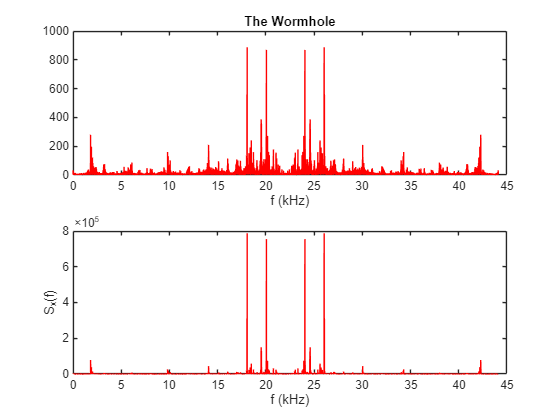


% Spettro (DFT)
S_x = abs(X).^2;

subplot(2,1,2);
plot(f, S_x, 'blue');
xlabel('f (kHz)');
ylabel('S_x(f)');
hold on

% Spettro (FFT)
S_y = abs(y).^2;

plot(f, S_y, 'red--');
hold off

## Su finestre specifiche

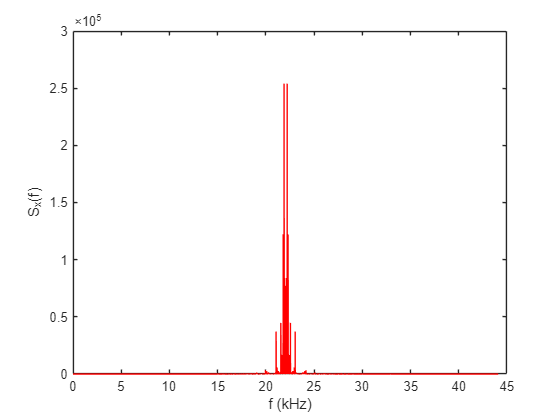

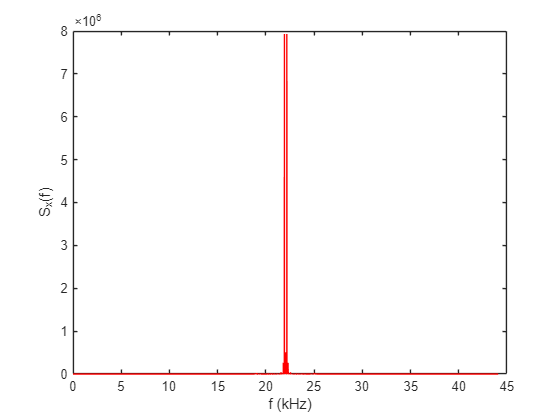

split_times = [15 30];
M_split = floor((length(classic)/div)/N);
n = 0:N-1;
for i = 1:length(split_times)
    current = split_times(i)/T_0;
    start = floor(1 + length(classic)/div*current);
    finish = floor(length(classic)/div + length(classic)/div*current);
    x = classic(start:M_split:finish);
    y = fftshift(abs(fft(x, N)));
    S_y = abs(y).^2;
    f = (n/N)*f_c/1000;
    figure(i+2);
    plot(f, S_y, 'red');

    xlabel('f (kHz)');
    ylabel('S_x(f)');
end

## --- Brano rock ---

## Informazioni di campionamento

disp('--- Informazioni di campionamento (brano rock) ---');

--- Informazioni di campionamento (brano rock) ---


% Parametri liberi
f_c = fs_rock                       % frequenza di campionamento

f_c = 44100

T_0 = 5                             % finestra temporale

T_0 = 5

n_bit = 16;                         % numero di bit
% Parametri derivati
T_c = 1/f_c;                        % periodo di campionamento
df = 1/T_0;                        
div = T_rock/T_0;                   % numero di finestre
N = 2^n_bit                         % numero di campioni

N = 65536

M = floor(length(rock)/N);

## Su brano intero

% DFT
x = rock(1:M:length(rock));
X = zeros(N,1);
H = exp(-i*2*pi/N);

xp = x(1:2:N);
xd = x(2:2:N);
Xp = zeros(N, 1);
Xd = zeros(N, 1);

disp("Eseguendo la DFT sull'intero brano rock...")

Eseguendo la DFT sull'intero brano rock...


tic
for k = 1:N
    for n = 1:N/2
        Xp(k) = Xp(k) + xp(n) * (H^(2*(n-1)*(k-1)));
        Xd(k) = Xd(k) + (H^(k-1)) * xd(n) * (H^(2*(n-1)*(k-1)));
    end
    X(k) = X(k) + Xp(k) + Xd(k);
end

n = 0:N-1;
f = (n/N)*f_c/1000;

X = fftshift(X);

figure(1)
subplot(2,1,1);
plot(f, abs(X), 'blue');
xlabel('f (kHz)');
title('Crazy Train')
hold on
toc

Elapsed time is 3014.057083 seconds.



% FFT 
disp("Eseguendo la FFT sull'intero brano rock...")

Eseguendo la FFT sull'intero brano rock...


tic
y = fftshift(abs(fft(x, N)));
n = 0:N-1;
f = (n/N)*f_c/1000;

plot(f, y, 'red');
hold off
toc

Elapsed time is 0.028933 seconds.


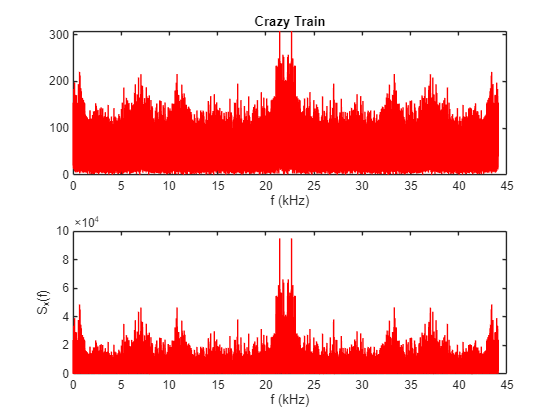


% Spettro (DFT)
S_x = abs(X).^2;

subplot(2,1,2);
plot(f, S_x, 'blue');
xlabel('f (kHz)');
ylabel('S_x(f)');
hold on

% Spettro (FFT)
S_y = abs(y).^2;

plot(f, S_y, 'red');
hold off

## Su finestre specifiche

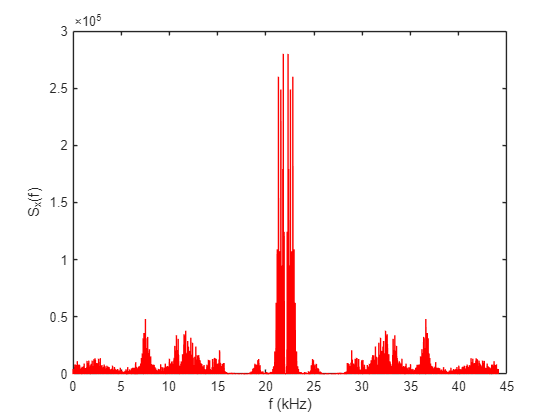

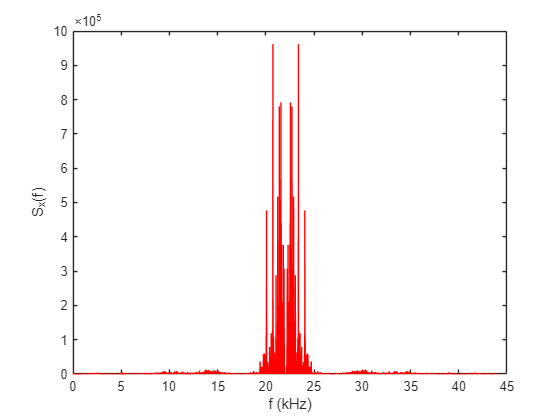

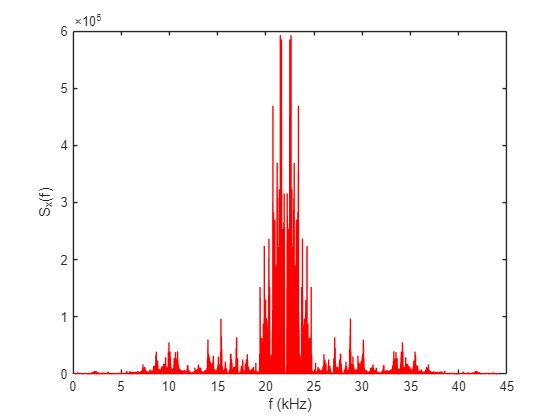

split_times = [10 35 70];
M_split = floor((length(rock)/div)/N);
n = 0:N-1;
for i = 1:length(split_times)
    current = split_times(i)/T_0;
    start = floor(1 + length(rock)/div*current);
    finish = floor(length(rock)/div + length(rock)/div*current);
    x = rock(start:M_split:finish);
    y = fftshift(abs(fft(x, N)));
    S_y = abs(y).^2;
    f = (n/N)*f_c/1000;
    
    figure(i+2);
    plot(f, S_y, 'red');

    xlabel('f (kHz)');
    ylabel('S_x(f)');
end